# Kalman Filter Practical

In this practical, you will get familiar with implementing the linear and extended Kalman filters and get more insight into tuning their parameters. In this task, the aim of using Kalman filters is to track the position of an autonomous vehicle using GPS and radar measurements. The dataset was recorded during the [HumanDrive](https://humandrive.co.uk/) trials on the Multi User Environment for Autonomous Vehicle Innovation ([MUEAVI](https://www.cranfield.ac.uk/facilities/mueavi)) experimental facility.

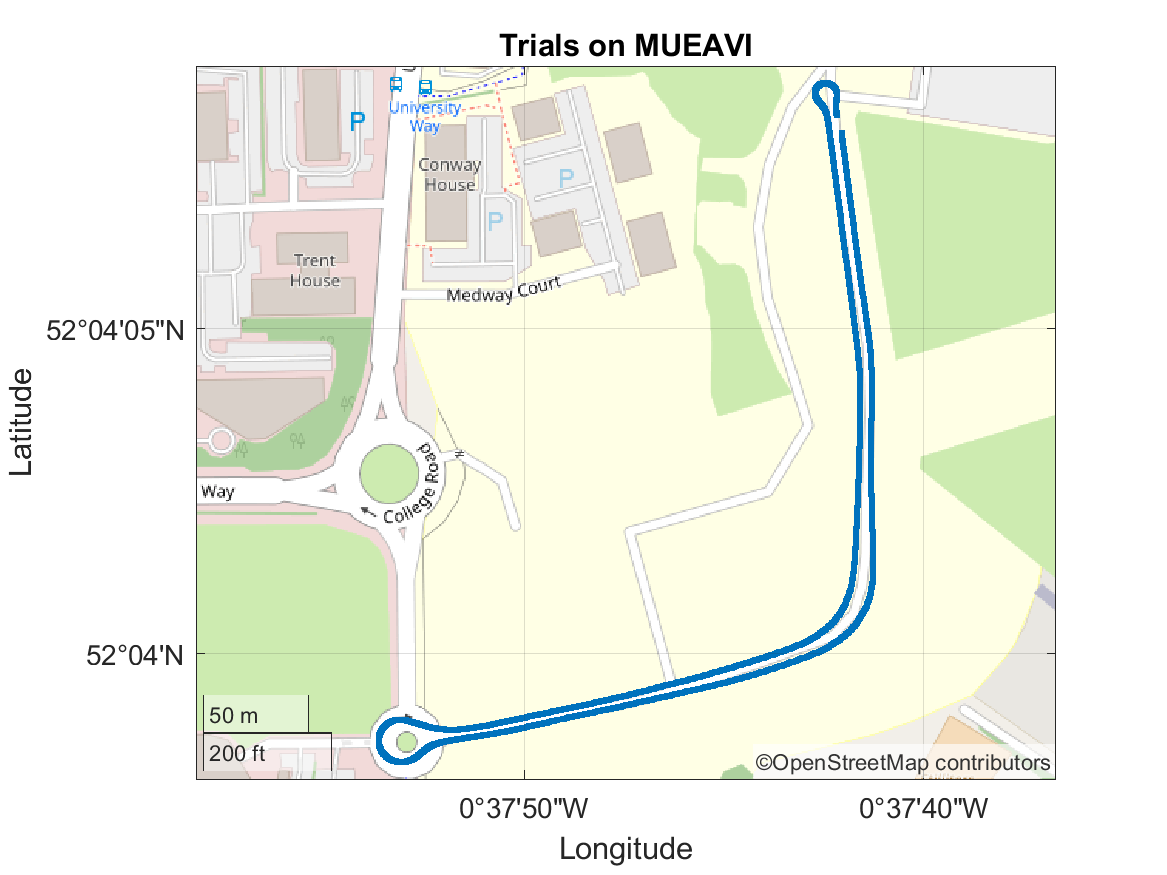

## Objectives

- Implement a linear Kalman filter to estimate the position and velocity of an autonomous vehicle from noisy GPS measurements.

- Implement an Extended Kalman filter to the 2D planar position and velocity of the same vehicle using a fusion of GPS and range-bearing measurements from a stationary radar sensor.

## Analyse the measurements

First of all, let's by loading the dataset `sensor_data.mat`, which contains the time vector, the X-Y global coordinates as noisy GPS measurements and radar measurements for the EKF task. The GPS measurements are already converted from longitude and latitude to meter units.

clear variables

load data\sensor_data.mat
variableNames'

% Time vector
t = data(:,1)-data(1,1);
dt = t(2)-t(1); % Uniform 0.1s time vector

The standard deviations of the measurement noise of the two sensors (GPS, radar) are believed to be: 


$$\begin{array}{l}
\sigma_{x,y} =0\ldotp 5\;\mathrm{m}\\
\sigma_r =1\;\mathrm{m}\\
\sigma_{\theta \;} ={10}^{-4} \;\textrm{rad}
\end{array}$$


load('groundtruth.mat', 'gt') % Ground truth signals
plot(data(:,2),data(:,3))
hold on
plot(gt(:,2),gt(:,3))
radar_location = [100,150];
plot(radar_location(1),radar_location(2),'ro','MarkerSize',8)
title('MUEAVI dataset')
xlabel('X coordinates [m]')
ylabel('Y coordinates [m]')
xlim([-50,350])
ylim([-50,350])
legend('GPS dataset','Ground Truth (GT)','Radar sensor location')
hold off

## Linear Kalman Filter (KF)

We assume that we can track the vehicle filtering the measurements with a dynamic model of the vehicle behaviour, of this generic form: ${\mathbf{x}}_k ={\textrm{Fx}}_{k-1} +{\textrm{Gu}}_{k-1} +{\mathbf{w}}_k$ where ${\mathbf{w}}_k$ is the noise, drawn by a process described by the covariance matrix ${\mathbf{Q}}_k$: $ \mathbf{w}_k \sim  \mathcal{N} (0, \mathbf{Q}_k)$.

Similarly, we assume that we have a measurement equation ${\mathit{\mathbf{z}}}_k ={\textrm{Hx}}_k +{\mathbf{v}}_k$ ; where ${\mathbf{v}}_k$, the measurement noise, drawn by a process described by the covariance matrix ${\mathbf{R}}_k$: $ \mathbf{v}_k \sim  \mathcal{N} (0, \mathbf{R}_k)$.

Define the standard deviation of the GPS measurements.

% Standard deviation of the GPS measurements from datasheet
sigma_x = []; % m
sigma_y = []; % m

We are going to use the Kalman Filter Algorithm to filter the noisy measurements of the GPS data, defined by measurement array **z**. We assume that we know **Q** and **R **and the initial state vector. We also assume that we don't know any input to the system **u**.

The first question is: what is the motion model? We don't really know what is **F** - it is a model choice and will strongly influence the tracking filter behaviour. Define the following vectors and matrices to initialize the Kalman filter.

### Case 1: Constant Velocity model

We are going to assume to track the vehicle by assuming a constant target velocity. This is a quite common choice in target/object tracking.

- Useful to model smooth target motion

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\;\;\dot{x\;} \;\;\dot{y} \right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack x_0 \;\;y_0 \;\;v_{x,0} \;\;v_{y,0} \right\rbrack }^T$=${\left\lbrack x_0 \;\;y_0 \;\;0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cccc}
1 & 0 & T & 0\\
0 & 1 & 0 & T\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

%% FILTER INITIALIZATION---------------------------------------------------
% F: system transition matrix
F = [];

% H: Measurement matrix
H = [];

% x: State vector initialisation
x = zeros(4,length(data));
% x0: initial state vector
x(:,1) = [];

How to initialise the covariance matrices? 

**R **can be simply defined accordingly to measurement standard deviation.

% R: Measurement noise covariance matrix
R = diag([]);

**Q **should be representitive of unmodelled effects and assume those as noise. For a CV model we could use accelerations as unmodelled effects. **Q** is often used for tuning. Let us start by computing the average acceleration along the x and y components:

%Compute velocities and accelerations from the dataset (use the smooth
%command with a couple of seconds window before taking any derivatives 
% to avoid inflating accelerations due to the presence of noise)
vx = gradient(smooth(data(:,2),20),t);
vy = gradient(smooth(data(:,3),20),t);
ax = gradient(smooth(vx,20),t);
ay = gradient(smooth(vy,20),t);

%Average acceleration:
ax_m = mean(abs(ax)); % m/s^2
ay_m = mean(abs(ay)); % m/s^2

You know that unmodelled effects of accelerations are $\delta v=a\;\delta t$ and $\delta s=a\;\delta t^2$

%Unmodelled effects of position and velocity:
ds_x = 0.5*ax_m*dt^2;
ds_y = 0.5*ay_m*dt^2;
dv_x = ax_m*dt;
dv_y = ay_m*dt;

% Q: Process noise covariance matrix
Q = []*diag([]);

**P **should reflect the covariance of the states and it is the hardest to initialise. In the worst case scenario you can still initialise it a diagonal matrix of small positive values and the KF will take care of it.

% P: State Covariance matrix (initial)
P = diag([]);

### Linear KF algorithm

Recalling from the lecture we have the following equations we need to implement:

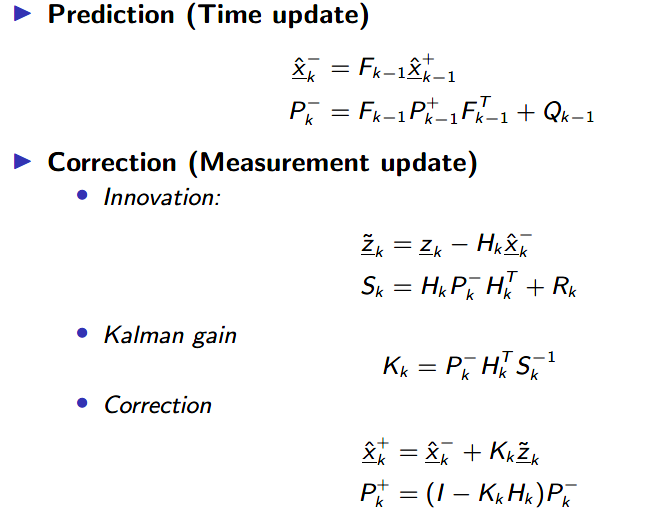

%% Linear KF algorithm-----------------------------------------------------
% Measurements array initialising
z = [data(:,2)'; data(:,3)'];

ChiStat = zeros(1,length(data));
for k = 2:length(data)
    %% Time Update ========================================================
    % Equation 1: State propagation
    xa = [];
    % Equation 2: State covariance propagation
    Pa = [];

    %% Measurement Update==================================================
    % Equation 3: Innovations
    dz = [];
    % Equation 4: Innovation covariance  
    S = [];  
    Yzz = S^(-1);     %Information matrix of innovations
    % Equation 5: Kalman gain
    K = []; 
    % Equation 6: State update
    x(:,k) = [];
    % Equation 7: Error covariance update
    P(:,:,k) = [];
    
    %% Compute Chi-squared statistics======================================
    ChiStat(k) = dz'*Yzz*dz;
end


Plot and analyse the results.

%% Plots-------------------------------------------------------------------
plot(data(:,1),data(:,2:3),data(:,1),x(1,:),data(:,1),x(2,:),gt(:,1),gt(:,2:3))
legend('x Measured','y Measured','x Filtered','y Filtered','x Ground truth','y Ground truth')
title('Measured, Filtered and Ground truth coordinates vs time')
xlabel('Time [s]')
ylabel('Measured position [m]')

plot(data(:,2),data(:,3),x(1,:),x(2,:),gt(:,2),gt(:,3))
legend('Measured','Filtered','Ground truth','Location',"northwest")
title('Car locus [X,Y]')
xlabel('X coordinate [m]')
ylabel('Y coordinate [m]')
axis equal

plot(t,ChiStat)
xlabel('Time [s]')
ylabel('\chi^2')
title('\chi^2 statistics about innovations')

### Experiment with the filter

Try to change the values of the **Q **matrix by multiplying it by a factor 1e-1 or 10.

- What changes in the results? 

- What changes in the innovations?

- Why?

### Optional - Case 2: Brownian Motion model

Try to run the KF again with the assumption that there is no-motion happening. 

- Useful to describe stop-and-go motion behaviour

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack 0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$

### Optional - Case 3: Constant Acceleration model

Try to run the KF again with the assumption that there is constant target acceleration. 

- Useful to model target motion that is smooth in position and velocity changes 

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\;\;\dot{x\;} \;\;\dot{y} \;\;\ddot{x} \;\;\ddot{y} \right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack x_0 \;\;y_0 \;\;0\;\;0\;\;0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cccccc}
1 & 0 & T & 0 & \frac{T^2 }{2} & 0\\
0 & 1 & 0 & T & 0 & \frac{T^2 }{2}\\
0 & 0 & 1 & 0 & T & 0\\
0 & 0 & 0 & 1 & 0 & T\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack$

## Extended Kalman Filter (EKF)

In this second task, we will use also the measurements from a stationary radar sensor, which includes the whole MUEAVI track in its field of view. The unit of the range and bearing measurements is meter and radians, respectively.

We will proceed in fusing these measurements with the GPS measurements used in the previous example.

clear variables

load data\sensor_data.mat
load data\groundtruth.mat
variableNames'

% Time vector
t = data(:,1)-data(1,1);
dt = t(2)-t(1); % Uniform 0.1s time vector

The standard deviations of the measurement noise of the two sensors (GPS, radar) are believed to be: 


$$\begin{array}{l}
\sigma_{x,y} =0\ldotp 5\;\mathrm{m}\\
\sigma_r =1\;\mathrm{m}\\
\sigma_{\theta \;} ={10}^{-4} \;\textrm{rad}
\end{array}$$


% Standard deviation from datasheet
sigma_x = []; % m/s
sigma_y = []; % m/s
sigma_r = []; % m/s
sigma_theta = []; % rad/s

### Case 1: Constant Velocity model

We are going to assume to track the vehicle by assuming a constant target velocity. This is a quite common choice in target/object tracking.

- Useful to model smooth target motion

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\;\;\dot{x\;} \;\;\dot{y} \right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack x_0 \;\;y_0 \;\;v_{x,0} \;\;v_{y,0} \right\rbrack }^T$=${\left\lbrack x_0 \;\;y_0 \;\;0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cccc}
1 & 0 & T & 0\\
0 & 1 & 0 & T\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

%% FILTER INITIALIZATION----------------------------------------------------
% F: system transition matrix
F = [];

% x: State vector
x = zeros(4,length(data));
%initial state vector
x(:,1) = [];

### Non-linear measurement model

In this case, the measurement model is going to be more complex, as it requires to define a non-linear relationship between cartesian and polar coordinates. Furthermore, we know that the location of the stationary radar sensor, which is used to detect the vehicle on the MUEAVI track is:


$$\left\lbrack \begin{array}{c}
x_r \\
y_r 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
100\\
150
\end{array}\right\rbrack \mathrm{m}$$


The measurement model has the following form, where the first two elements are the GPS measurements in global X-Y coordinatesand the third and fourth elements are range and bearing from the radar.


$${\mathbf{z}}_k =h\left({\mathbf{x}}_k \right)=\left\lbrack \begin{array}{c}
x\\
y\\
\sqrt{{\left(x-x_r \right)}^2 +{\left(y-y_r \right)}^2 }\\
\tan^{-1} \left(\frac{y-y_r }{x-x_r }\right)
\end{array}\right\rbrack$$


% H: Measurement function (non-linear) - you can use an anonymous function
% with argument input @(x) and parameters xb, yb
xr = 100; % [m] X location of the radar
yr = 150; % [m] Y location of the radar

h_nl = @(x) [];

**Q **process noise covariance matrix represents the unmodelled effects and assume those as noise. You can copy your code from here, where you defined **Q **for the linear KF with the CV model.

%Compute velocities and accelerations from the dataset (use the smooth
%command with a couple of seconds window before taking any derivatives 
% to avoid inflating accelerations due to the presence of noise)
vx = gradient(smooth(data(:,2),20),t);
vy = gradient(smooth(data(:,3),20),t);
ax = gradient(smooth(vx,20),t);
ay = gradient(smooth(vy,20),t);

%Average acceleration:
ax_m = mean(abs(ax)); % m/s^2
ay_m = mean(abs(ay)); % m/s^2

You know that unmodelled effects of accelerations are $\delta v=a\;\delta t$ and $\delta s=a\;\delta t^2$

%Unmodelled effects of position and velocity:
ds_x = 0.5*ax_m*dt^2;
ds_y = 0.5*ay_m*dt^2;
dv_x = ax_m*dt;
dv_y = ay_m*dt;

% Q: Process noise covariance matrix
Q = []*diag([]);

**P **should reflect the covariance of the states and it is the hardest to initialise. As we use the same Constant Velocity (CV) motion model as before at the Linear Kalman Filter task, we can use the same initialization as well. Copy your code from here.

% P: State Covariance matrix (initial)
P = diag([]);

**R **measurement noise covariance matrix differ from the one before, because the measurement vector now contains the radar detections also. It can be defined accordingly to the measurement standard deviations as a diagonal matrix.

% R: Measurement noise covariance matrix
R = diag([]);

### EKF algorithm

Review and implement the EKF algorithm

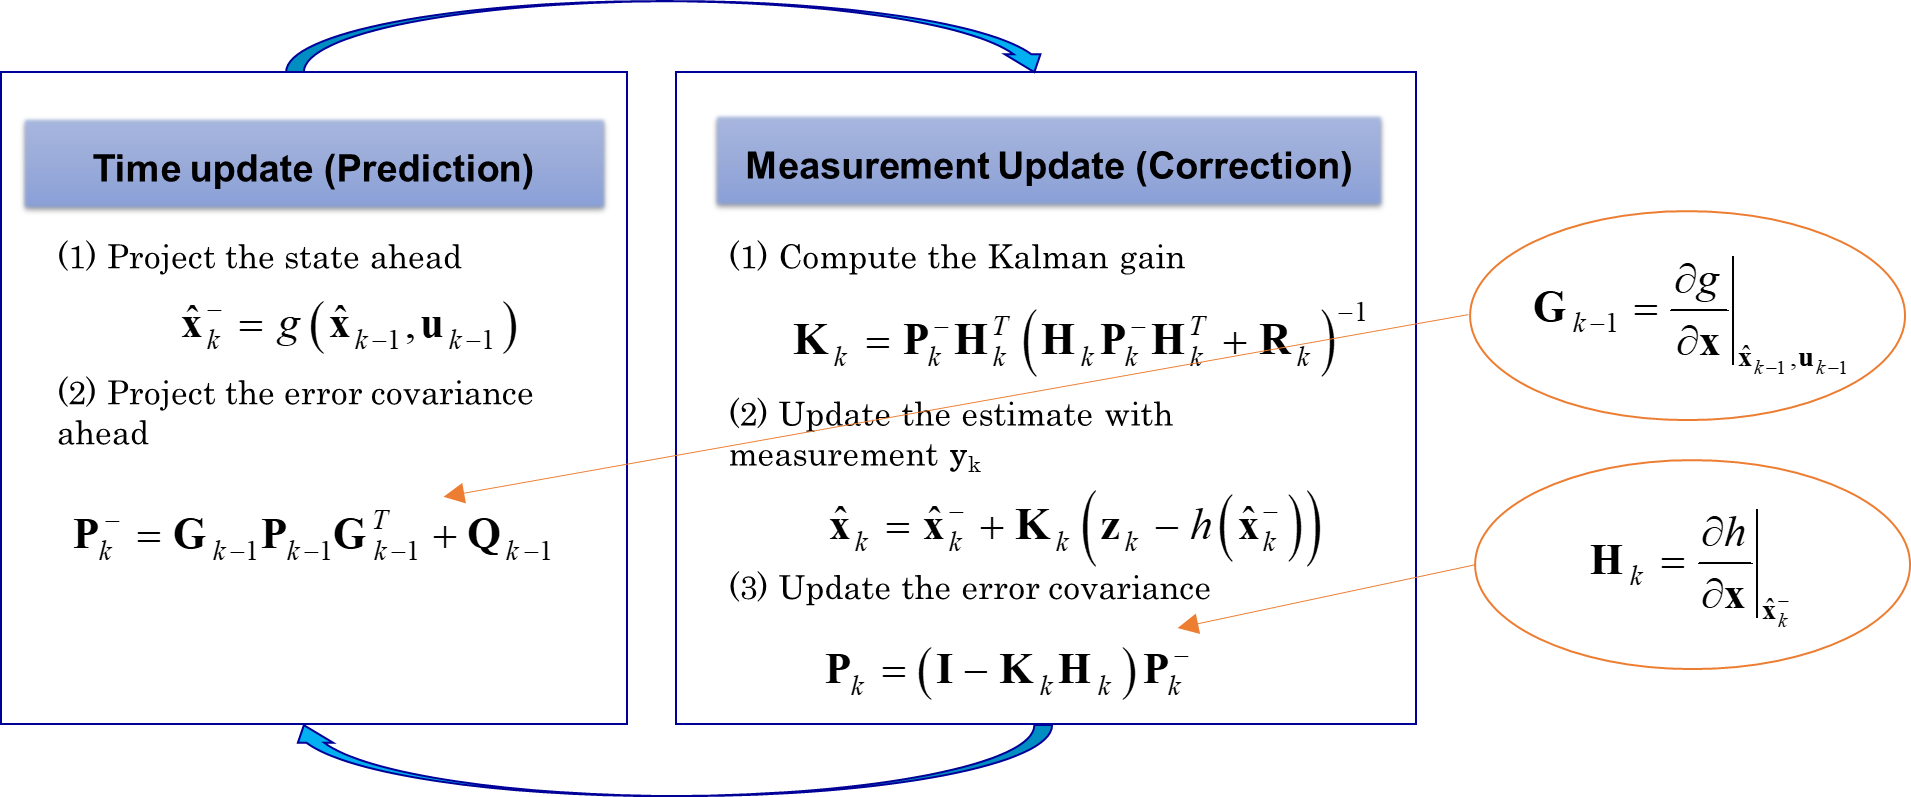

Please notice that the Jacobian matrix needs to be updated on the light of the two GPS measurements:

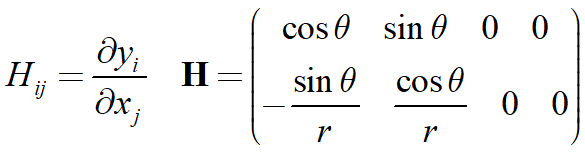

The correct dimension of $\mathbf{H}$ should be 4x4 as the number of states and number of measurements suggests.

% Measurements initialisation
z = [data(:,2)';data(:,3)';data(:,4)';data(:,5)'];

%% EKF Filter algorithm-----------------------------------------------------
ChiStat = zeros(1,length(data));
for k = 2:length(data)
    %% Time Update ==============================================
    % Equation 1: State propagation
    xa = [];
    % Equation 2: State covariance propagation
    Pa = [];

    %% Measurement Update======================================== 
    za = []; %Predicted measurements using a priori states
    
    % Jacobian matrix: linearization of the measurement model
    H = [];
    
    % Equation 3: Innovation
    S = [];  %Innovation covariance
    Yzz = S^(-1);     %Information matrix of innovations
    
    % Equation 4: Kalman gain
    K = []; 
    
    % Equation 5: State update
    dz = []; %Innovations (using full non-linear model)
    x(:,k) = []; %State update
    
    % Equation 6: Error covariance update
    P(:,:,k) = [];
    
    % Compute Chi-squared statistics:
    ChiStat(k) = dz'*Yzz*dz;
end

%% POST-PROCESSING
%Compute the filtered measurements (using filtered states and the full non-linear
%measurement model):
z_post = h_nl(x);

Plot and analyse the results.

%Plots: time-histories-----------------------------------------------------
plot(data(:,1),data(:,2:3),data(:,1),x(1,:),data(:,1),x(2,:),gt(:,1),gt(:,2:3))
legend('x Measured','y Measured','x Filtered','y Filtered','x Ground truth','y Ground truth')
title('Measured, Filtered and Ground truth coordinates vs time')
xlabel('Time [s]')
ylabel('Measured position [m]')

plot(data(:,2),data(:,3),x(1,:),x(2,:),gt(:,2),gt(:,3))
legend('Measured','Filtered','Ground truth','Location',"northwest")
title('Car locus [X,Y]')
xlabel('X coordinate [m]')
ylabel('Y coordinate [m]')
axis equal

plot(t,data(:,4),t,z_post(3,:),gt(:,1),gt(:,4))
legend('r Measured','r Filtered','r Ground truth')
title('Measured, Filtered and Ground truth range vs time')
xlabel('Time [s]')
ylabel('Measured range r [m]')

plot(t,data(:,5),t,z_post(4,:),gt(:,1),gt(:,5))
title('Measured, Filtered and Ground truth bearing angle vs time')
legend('\theta Measured','\theta Filtered','\theta Ground truth','Location',"southeast")
xlabel('Time [s]')
ylabel('Measured \theta [rad]')

plot(t,ChiStat)
xlabel('Time [s]')
ylabel('\chi^2')
title('\chi^2 statistics about innovations')

### Experiment with the filter

Try to change the values of the **Q **matrix by multiplying it by a factor 1e-1 or 10.

- What changes in the results? 

- What changes in the innovations?

- Why?

### Compare the performance of KF and EKF

Compare the performance of the two filters. You may want to save the data of the linear KF to plot and compare with the EKF data.

%Compare the performance



### Optional - Case 2: Brownian Motion model

Try to run the EKF again with the assumption that there is no-motion happening. 

- Useful to describe stop-and-go motion behaviour

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack 0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$

### Optional - Case 3: Constant Acceleration model

Try to run the EKF again with the assumption that there is constant target acceleration. 

- Useful to model target motion that is smooth in position and velocity changes 

- State representation: $\mathbf{x}={\left\lbrack x\;\;y\;\;\dot{x\;} \;\;\dot{y} \;\;\ddot{x} \;\;\ddot{y} \right\rbrack }^T$

- Initial state: ${\mathbf{x}}_0 ={\left\lbrack x_0 \;\;y_0 \;\;0\;\;0\;\;0\;\;0\right\rbrack }^T$

- State transition matrix: $\mathbf{F}=\left\lbrack \begin{array}{cccccc}
1 & 0 & T & 0 & \frac{T^2 }{2} & 0\\
0 & 1 & 0 & T & 0 & \frac{T^2 }{2}\\
0 & 0 & 1 & 0 & T & 0\\
0 & 0 & 0 & 1 & 0 & T\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack$